# Basic Calcs

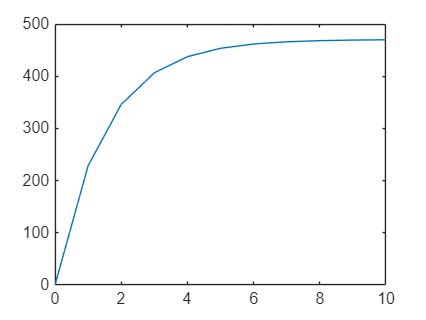

V_acc = 470.4; 
R_precharge = 800; 
C_inv = 1.88 * 10^(-3);
R1 = 91000; 
R2 = 510; 

t = 0:1:10; 
V_ts = V_acc * (1-exp(-t/(R_precharge*C_inv))); 

figure 
plot(t,V_ts); 


V_L = V_acc * (R2/(R1+R2)); 
V_90 = (V_L*0.9)/V_acc; 
R3 = (V_90*(R1+R2))/(1-V_90); 
disp(R3); 

  461.3139



## Simulation Check

t = out.ScopeData.time; 
